clear all
clc

opts = delimitedTextImportOptions("NumVariables", 22);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["EncoderPosition", "StepPosition", "Speed", "EngineCurrent", "EngineVoltage", "PowerCurrent", "PowerVoltage", "USBCurrent", "USBVoltage", "CurrentA", "CurrentB", "CurrentC", "VoltageA", "VoltageB", "VoltageC", "PWMLevel", "Temperature", "Joystick", "AnalogInput", "Time", "GeneralFlags", "GPIOFlags"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
xilabData = readtable("xilab9.csv", opts);
opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Times", "Channel5"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
digital = readtable("digital.csv", opts)

digital = 144027×2 table
    Times     Channel5
    ______    ________

    11.469       1    
    11.472       0    
    11.475       1    
    11.477       0    
    11.479       1    
    11.481       0    
    11.482       1    
    11.484       0    
    11.485       1    
    11.486       0    
    11.488       1    
    11.489       0    
     11.49       1    
    11.491       0    
    11.492       1    
    11.493       0    





clear opts




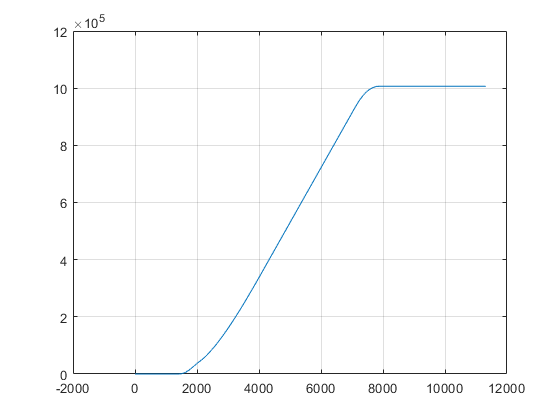

plot(xilabData.Time,xilabData.EncoderPosition);
grid on
hold off

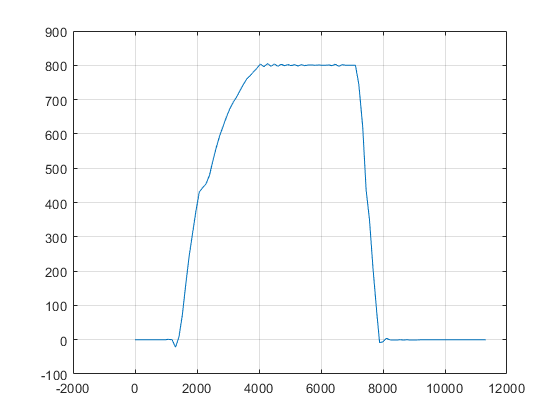

velocity = zeros(1,length(xilabData.EncoderPosition))';

for i = 1:length(xilabData.EncoderPosition)-1
    velocity(i) = (xilabData.EncoderPosition(i+1) - xilabData.EncoderPosition(i))/(xilabData.Time(i+1) - xilabData.Time(i));
end
velocity(velocity < 0) = [];
velocity = xilabData.Speed;
plot( xilabData.Time,velocity)
grid on
hold off

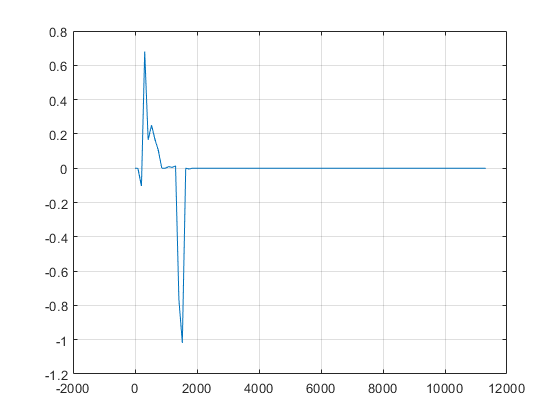


acceleration = zeros(1, length(xilabData.EncoderPosition))';
j = 1;
for i = 1:5:length(velocity)-2
    acceleration(j) = (velocity(i+2) - velocity(i)) / (xilabData.Time(i+2) - xilabData.Time(i));
    j = j+1;
end

plot(xilabData.Time,acceleration)
grid on
hold off

t = digital.Times(digital.Channel5 == 1)

t =    11.4690
   11.4749
   11.4791
   11.4824
   11.4852
   11.4876
   11.4899
   11.4919
   11.4938
   11.4956


t = round(t, 5);
t = t(1:end)

t =    11.4690
   11.4749
   11.4791
   11.4824
   11.4852
   11.4876
   11.4899
   11.4919
   11.4938
   11.4956


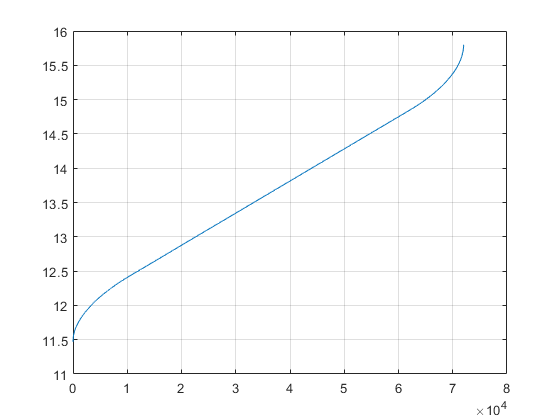

s = 2*pi/3600;
figure
plot(t);
grid on
hold off

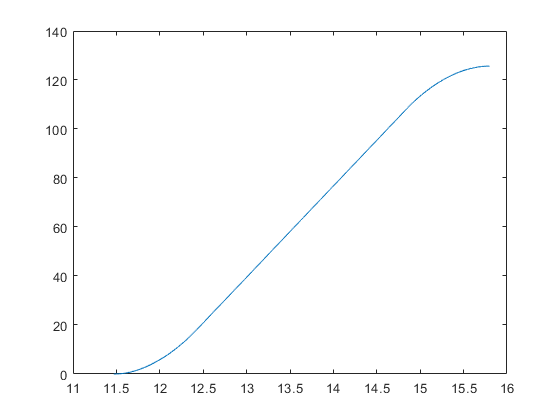

rouns = 1:length(t);
rouns= rouns * s;
rouns = rouns';
plot(t, rouns);


v = 0;
tt = 0

tt = 0

j = 1;
step = 100

step = 100

for i = 2 :step : length(t)-step
    
    dt(j) = (t(i+step)-t(i));
    tt(j) = t(i);
    v(j) = s*step/dt(j);
    j = j+1;
end
v = smooth(v, 0.05)

v =     1.9610
    4.2582
    5.8265
    7.0390
    7.9406
    8.6741
    9.3211
    9.9251
   10.5115
   11.0903


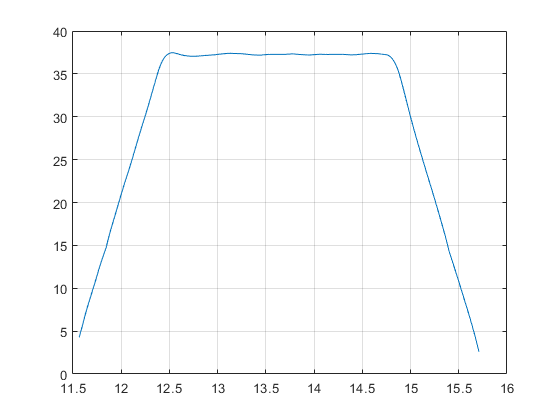

plot(tt(2:length(v)),v(2:end))
grid on



acc = 0

acc = 0

j = 1;
ttt = 0;
for i = 1: length(v)-1
    
    acc(i) = ((v(i+1)-  v(i))/ (tt(i+1) - tt(i)));

end

acc = smooth(acc,0.1)

acc =    25.8108
   36.7710
   37.2740
   36.9240
   36.9485
   37.1707
   37.0084
   36.4378
   35.8066
   36.9740


acc = acc(4:20)

acc =    36.9240
   36.9485
   37.1707
   37.0084
   36.4378
   35.8066
   36.9740
   37.4004
   37.5153
   37.5472


acc = smooth(acc)

acc =    36.9240
   37.0144
   36.8979
   36.6744
   36.6795
   36.7254
   36.8268
   37.0487
   37.4056
   37.5375


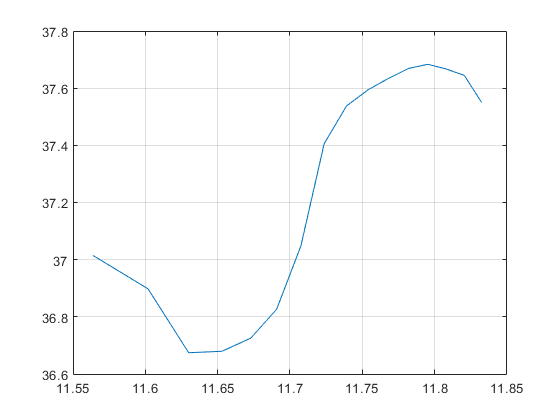

plot( tt(2:length(acc)),acc(2:end))
grid 

Km = 0.05

Km = 0.0500

M = 2.681*10^-4

M = 2.6810e-04

sigma = M/Km

sigma = 0.0054


Is = 2/(12.2*1000)

Is = 1.6393e-04

Ds = 1200/(186*1000)

Ds = 0.0065

Ps = 40000/(11500*1000)

Ps = 0.0035


sigma = Ps

sigma = 0.0035

Kp = 11500*sigma * 1000

Kp = 40000

Kd = 186*sigma * 1000

Kd = 646.9565

ki = 12.2*sigma*1000

ki = 42.4348